Load data

data=preprocess('data/korea.csv');
[tr,y_tr,te,y_te] = train_test_split(data);

OLS      

[beta,stats] = ols(tr,y_tr);

stats = struct with no fields.


stats = struct with fields:
    sigma2: 1.6298e+04


stats = struct with fields:
        sigma2: 1.6298e+04
    sample_var: [18×18 double]


stats = struct with fields:
        sigma2: 1.6298e+04
    sample_var: [18×18 double]
     std_error: [18×1 double]


stats = struct with fields:
        sigma2: 1.6298e+04
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 10.0028


stats = struct with fields:
        sigma2: 1.6298e+04
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 10.0028
           BIC: 10.7706


stats = struct with fields:
        sigma2: 1.6298e+04
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 10.0028
           BIC: 10.7706
            R2: 0.9988


stats = struct with fields:
        sigma2: 1.6298e+04
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 10.0028
           BIC: 10.7706
            R2: 0.9988
        adj_R2: 0.9978


[result] = test_model(beta,te,y_te);

result = struct with no fields.


result = struct with fields:
    residuals: [10×1 double]
          SSE: 1.2418e+08
          SST: 2.9153e+07


result = struct with fields:
    residuals: [10×1 double]
          SSE: 1.2418e+08
          SST: 2.9153e+07
           R2: -3.2596




x = 1:1:size(te)

x =      1     2     3     4     5     6     7     8     9    10


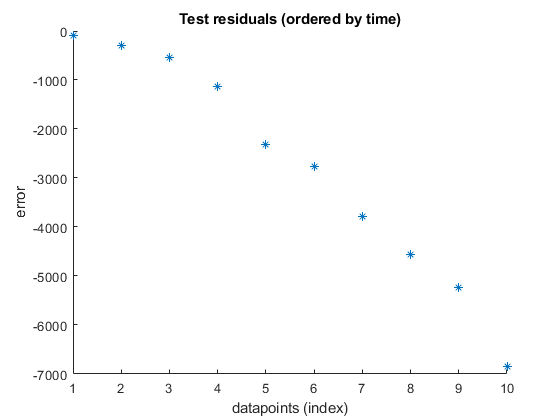

scatter(x,result.residuals,'*')
ylabel('error') 
xlabel('datapoints (index)') 
title('Test residuals (ordered by time)')